# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.8 节点到节点传播图

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

原问题：[https://www.zhihu.com/question/532006668/answer/2484306700](https://www.zhihu.com/question/532006668/answer/2484306700)

# 这种信息由一个节点传播到其他节点的图用MATLAB怎么画呀？

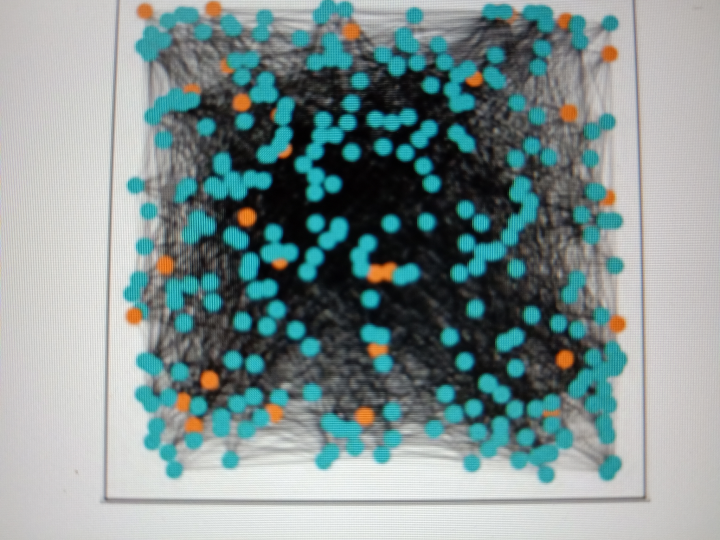

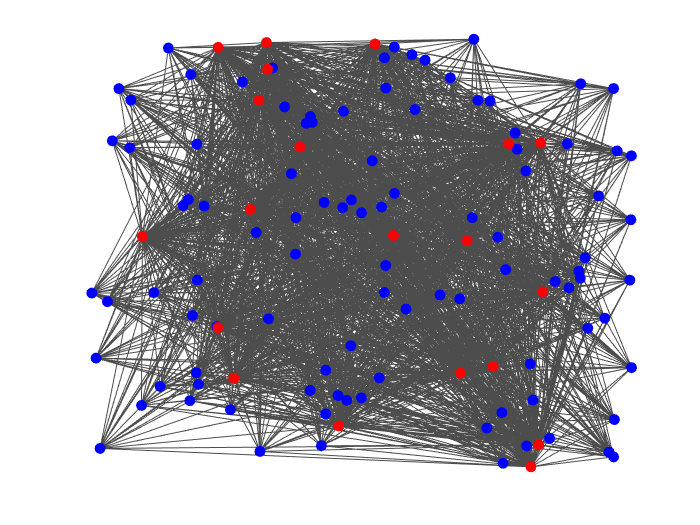

clear;clc;
x1 = rand(100, 1);
y1 = rand(100, 1);
x2 = rand(20, 1);
y2 = rand(20, 1);
% 连接线
for i = 1:length(x1)
    for j = 1:length(x2)
        plot([x1(i), x2(j)], [y1(i), y2(j)], 'Color', [0.3, 0.3, 0.3]);
        hold on
    end
end
% 节点
plot(x1, y1, 'ob', 'MarkerFaceColor', 'b');
plot(x2, y2, 'or', 'MarkerFaceColor', 'r');
hold off
axis off